Question 1.

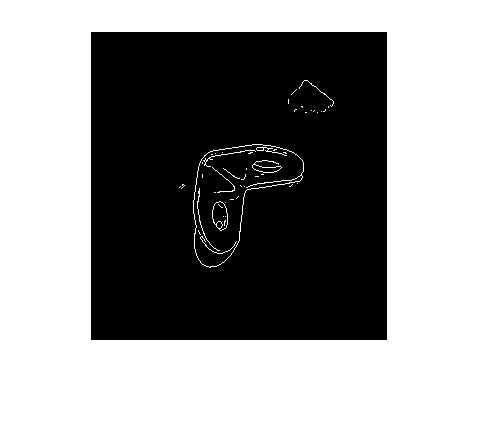

I = imread("parts/b0.jpg");
%[row, columns, rgb] = size(I)
%imshow(I);
BW = edge(I(:,:,1)) | edge(I(:,:,2)) | edge(I(:,:,3));
imshow(BW);


I = imread("parts/b0.jpg");
%[row, columns, rgb] = size(I)
%imshow(I);
BW = edge(I(:,:,1)) | edge(I(:,:,2)) | edge(I(:,:,3));
imshow(BW);

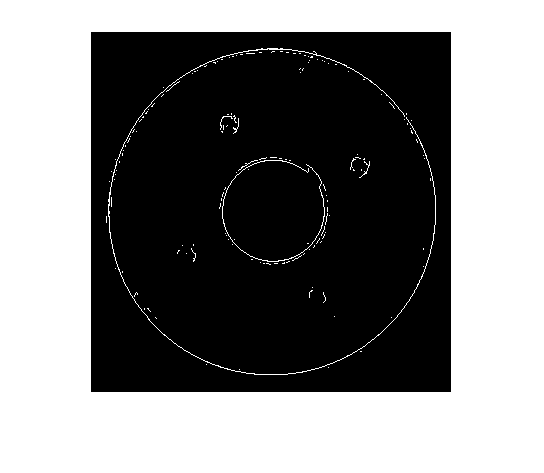

I = imread("parts/w0.jpg");
BW = edge(I(:,:,1)) | edge(I(:,:,2)) | edge(I(:,:,3));
imshow(BW);

I = imresize(I, [32,32]);
%[row, columns, rgb] = size(I)
BW = edge(I(:,:,1)) | edge(I(:,:,2)) | edge(I(:,:,3))

BW = 32×32 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0

Imgvector = BW(:);
Imgvector = reshape(BW, 1, [])

Imgvector = 1×1024 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1


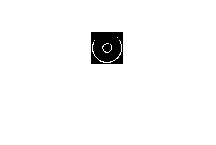

imshow(BW);

fid = fopen('hw1p4_data.csv');

readData = textscan(fid,'%f %f %f','Delimiter',',');

X = readData{1,1}(:,1);
Y = readData{1,2}(:,1);
Z = readData{1,3}(:,1);

Scatter Plots:

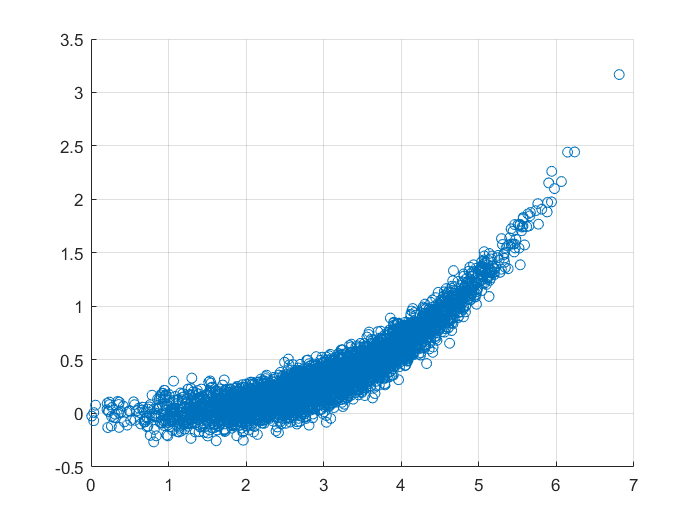

cla; hold on; grid on;
scatter(X,Y);

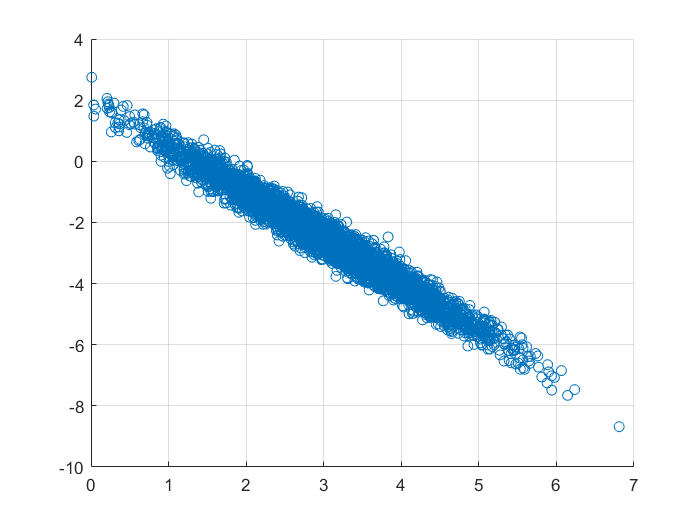

cla; hold on; grid on;
scatter(X,Z);

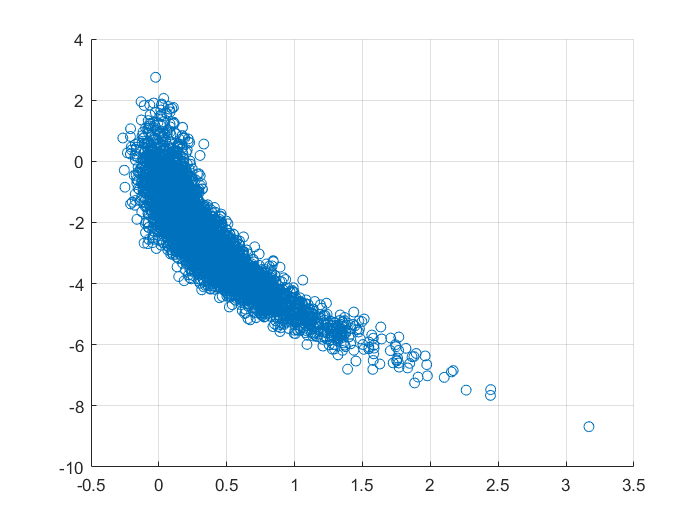

cla; hold on; grid on;
scatter(Y,Z);


N = numel(X);
CovXY = (X-mean(X))'*(Y-mean(Y))/(N-1);
CovYX = CovXY;
CovXZ = (X-mean(X))'*(Z-mean(Z))/(N-1);
CovZX = CovXZ;
CovYZ = (Y-mean(Y))'*(Z-mean(Z))/(N-1);
CovZY = CovYZ;

Mean = [mean(X); mean(Y); mean(Z)]

Mean =     3.0323
    0.3687
   -2.5519


CovMx = [var(X) CovXY CovXZ;
         CovYX  var(Y) CovYZ;
         CovZX  CovZY  var(Z)]

CovMx =     0.9714    0.2922   -1.4537
    0.2922    0.1133   -0.4371
   -1.4537   -0.4371    2.2644


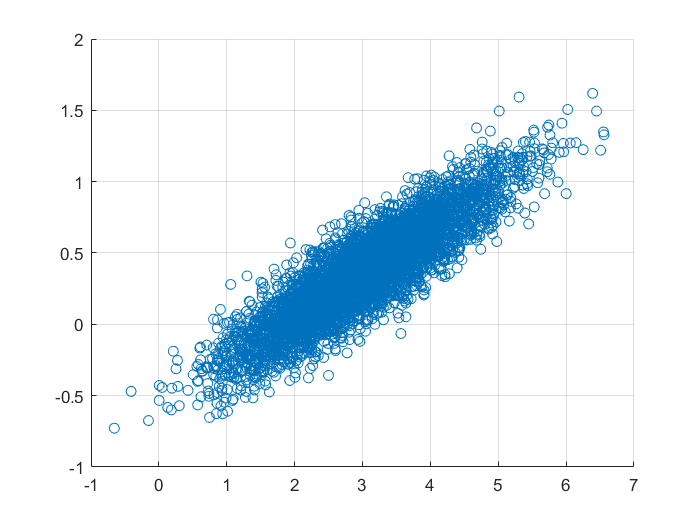

     
rng('default');
R = mvnrnd(Mean,CovMx,N);

cla; hold on; grid on;
scatter(R(:,1),R(:,2));

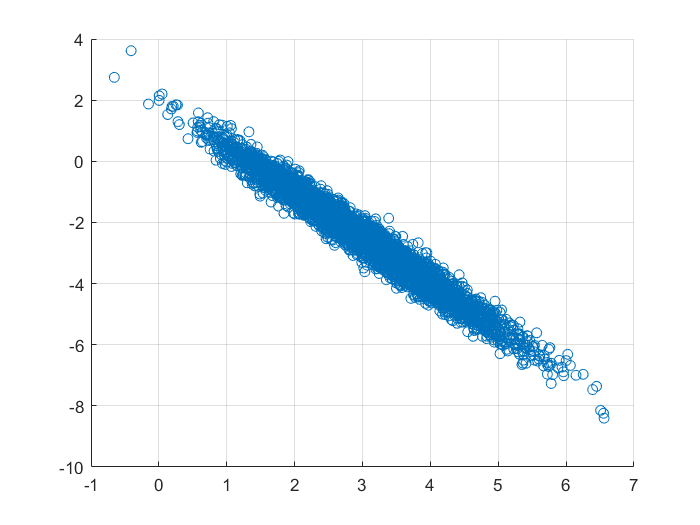

cla; hold on; grid on;
scatter(R(:,1),R(:,3));

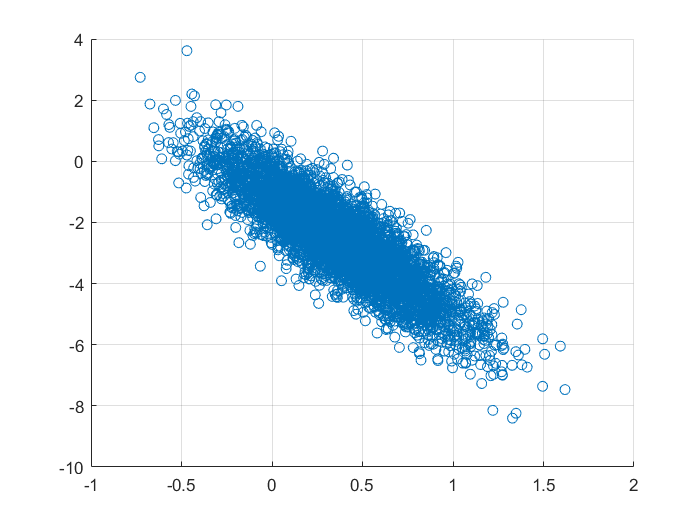

cla; hold on; grid on;
scatter(R(:,2),R(:,3));

% A = [1 2;2 5;3 6;4 7;5 1];
% sum(A,2)
% n= 10;
% m = 20;
% mat = zeros(n,1)

mat =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


% mat(1,1) = 2;
% mat

mat =      2
     0
     0
     0
     0
     0
     0
     0
     0
     0


Question 5.

Training set size 10


n = 1

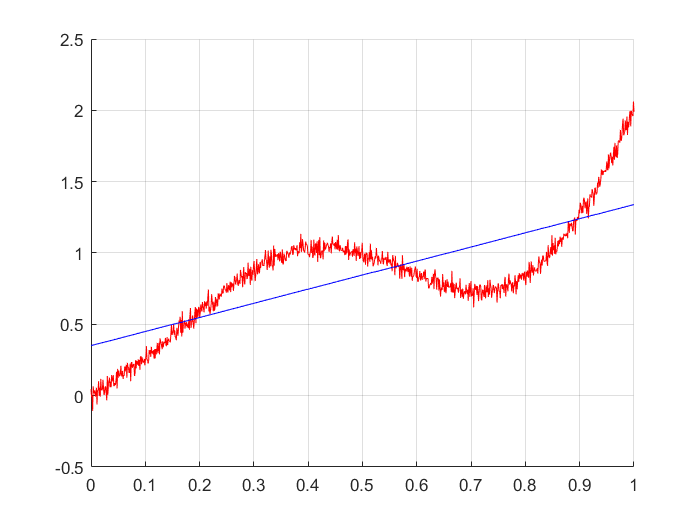

MSE = 0.0725

n = 2

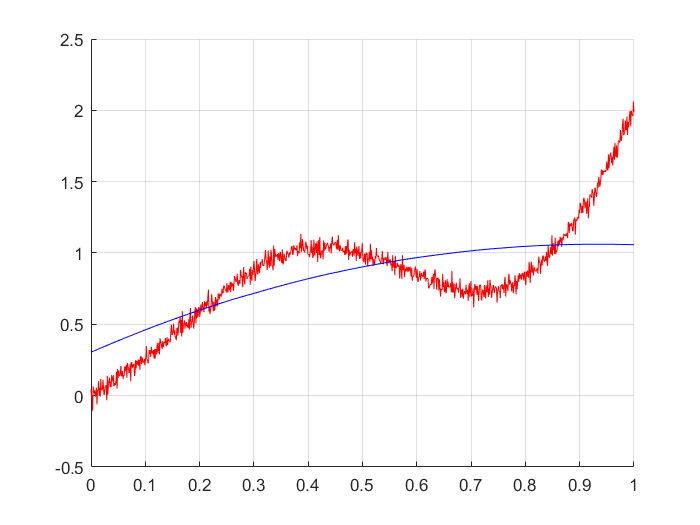

MSE = 0.1375

n = 3

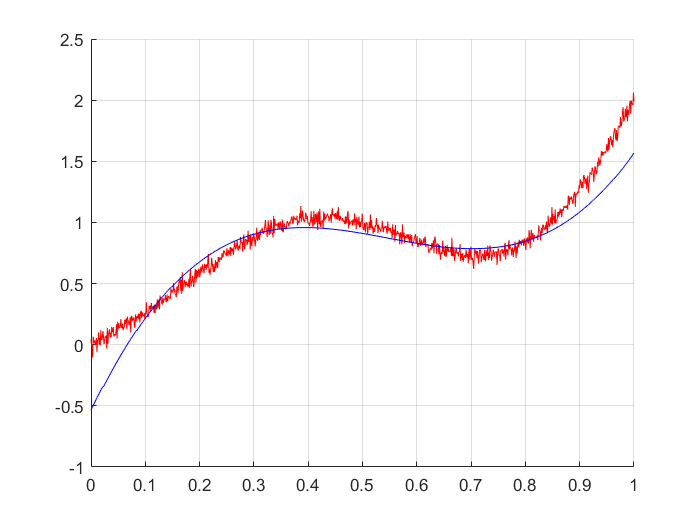

MSE = 0.1106

n = 4

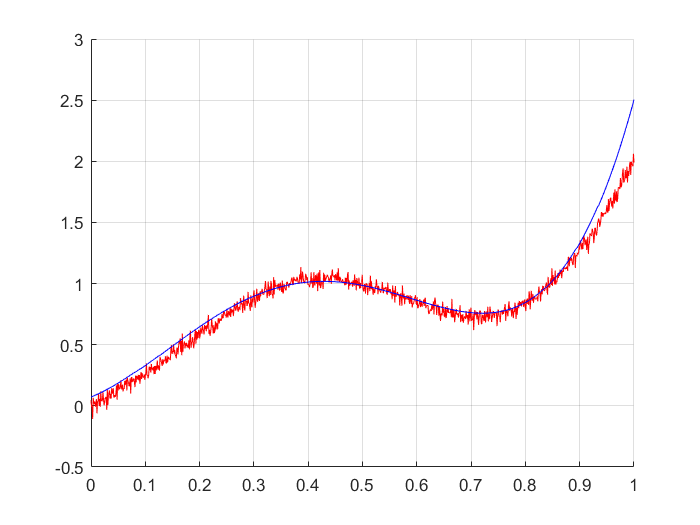

MSE = 0.4503

n = 5

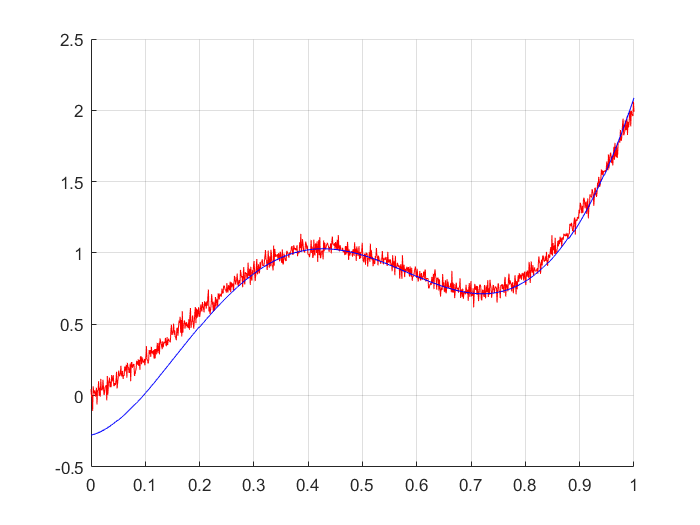

MSE = 1.9947

n = 6

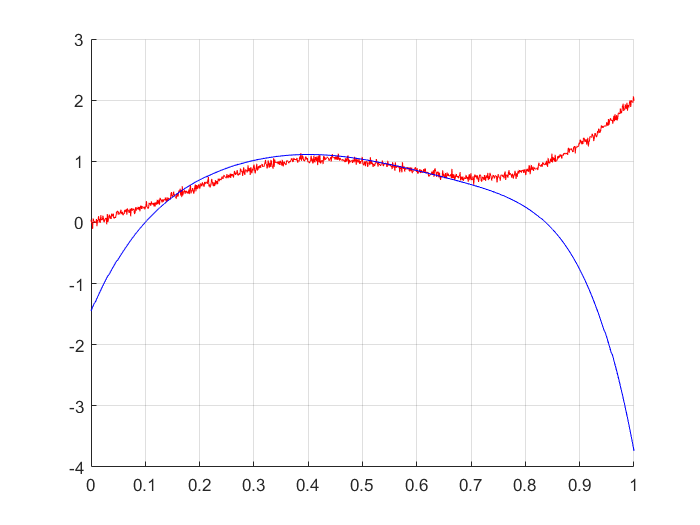

MSE = 154.7379

n = 7

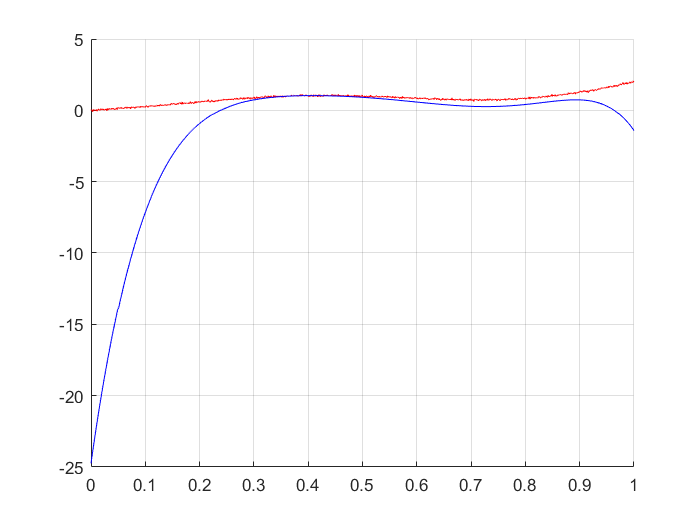

MSE = 4.4650e+03

n = 8

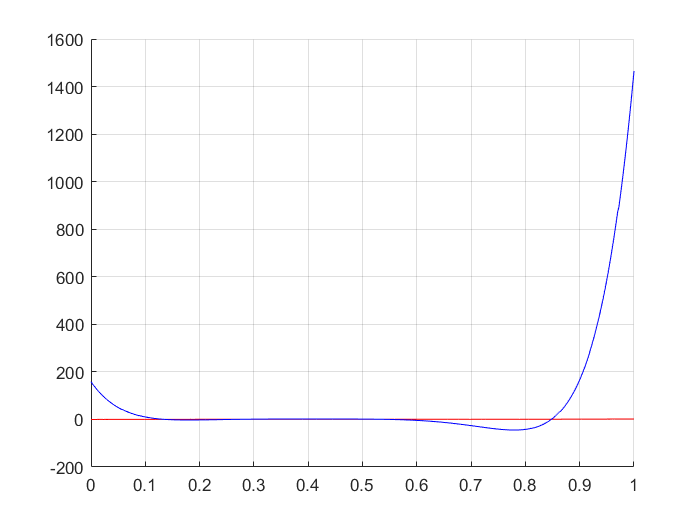

MSE = 7.5578e+06

n = 9

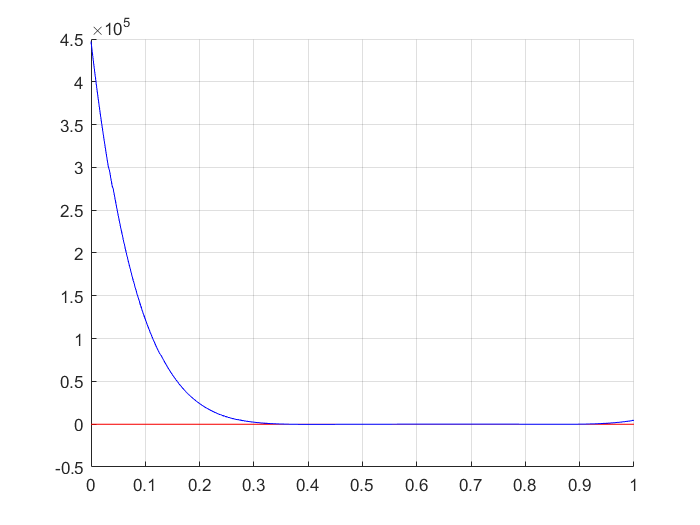

MSE = 7.5487e+11

n = 10

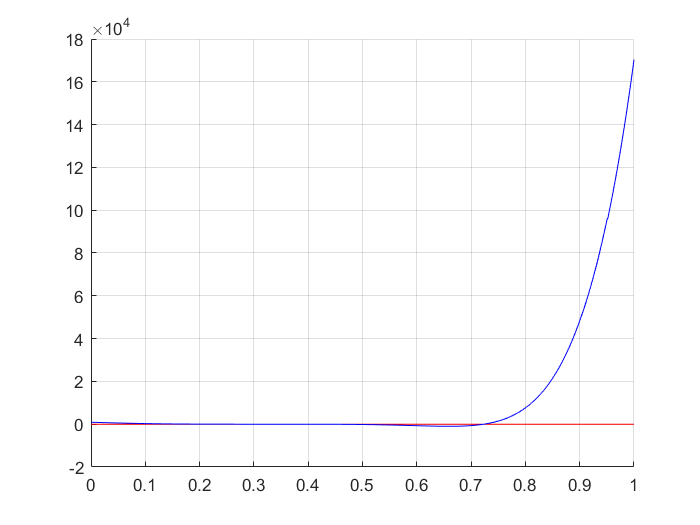

MSE = 1.2856e+11

Training set size 15


n = 1

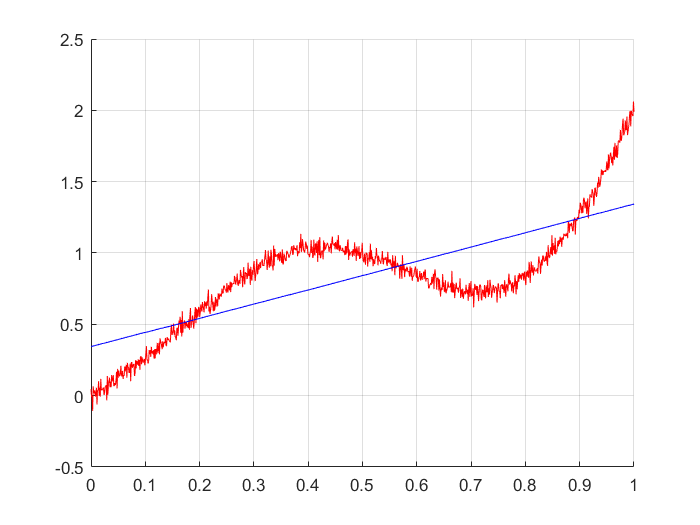

MSE = 0.0702

n = 2

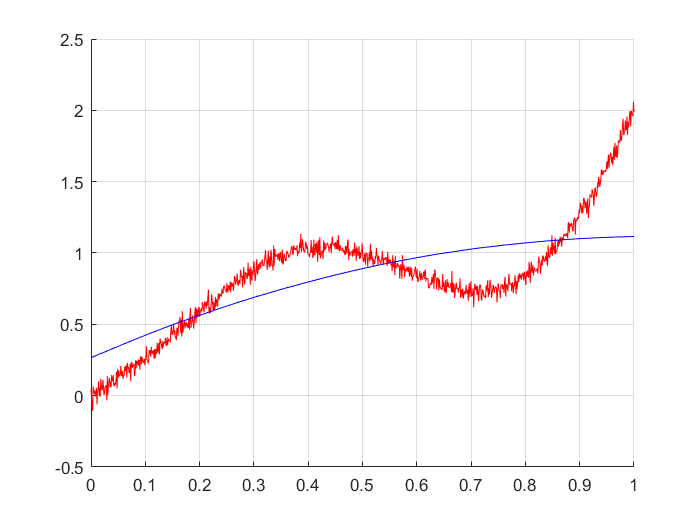

MSE = 0.1060

n = 3

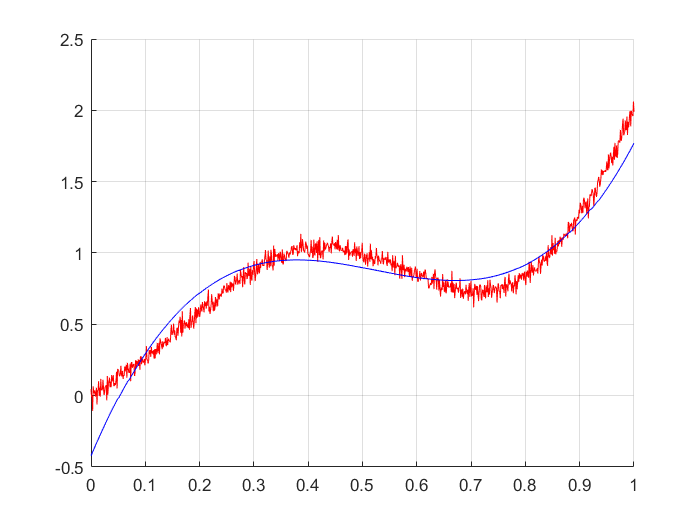

MSE = 0.0385

n = 4

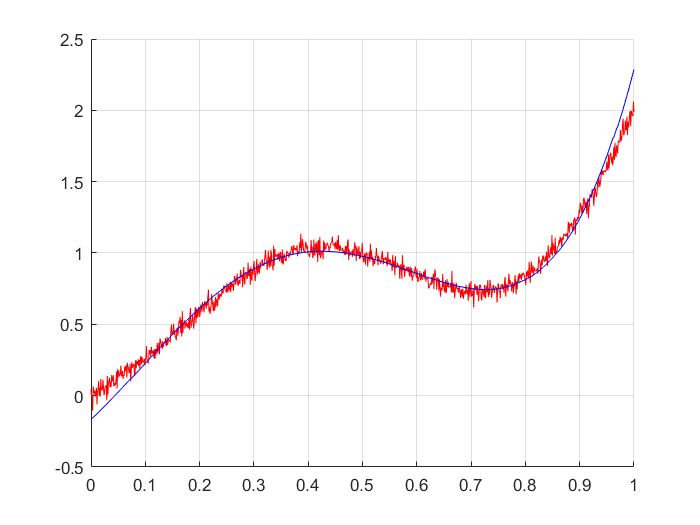

MSE = 0.0418

n = 5

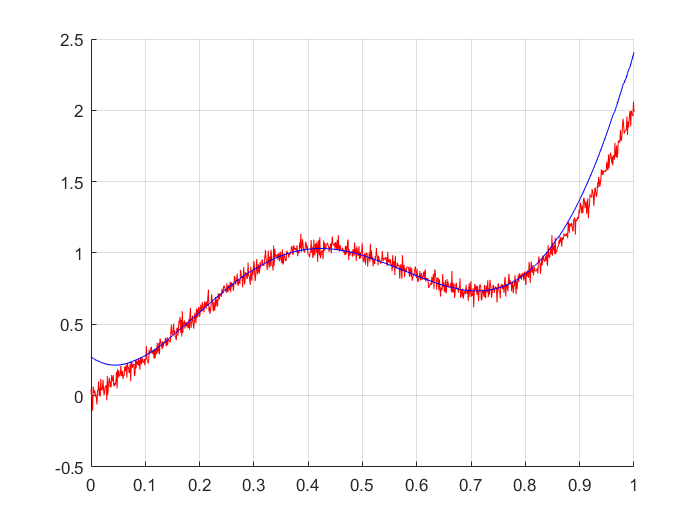

MSE = 0.1090

n = 6

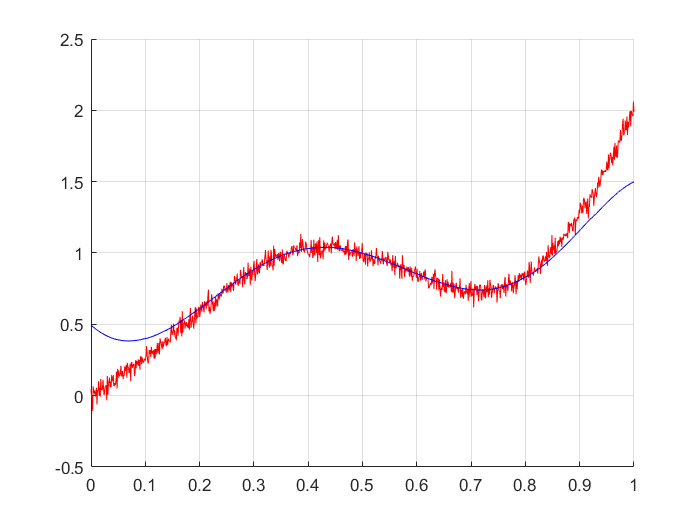

MSE = 0.8448

n = 7

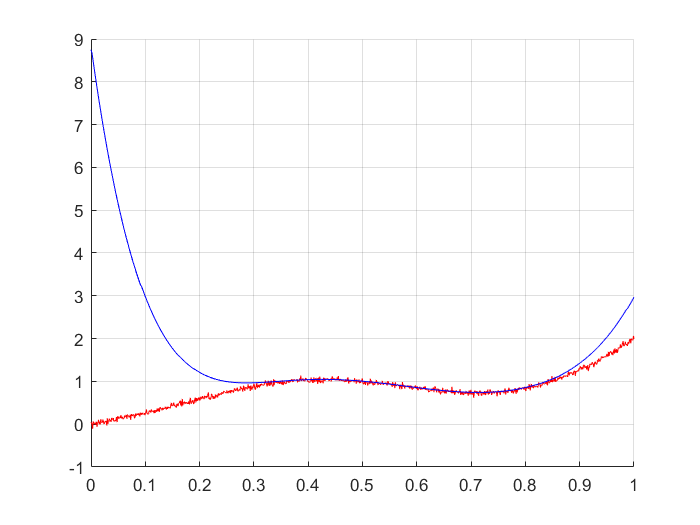

MSE = 316.6674

n = 8

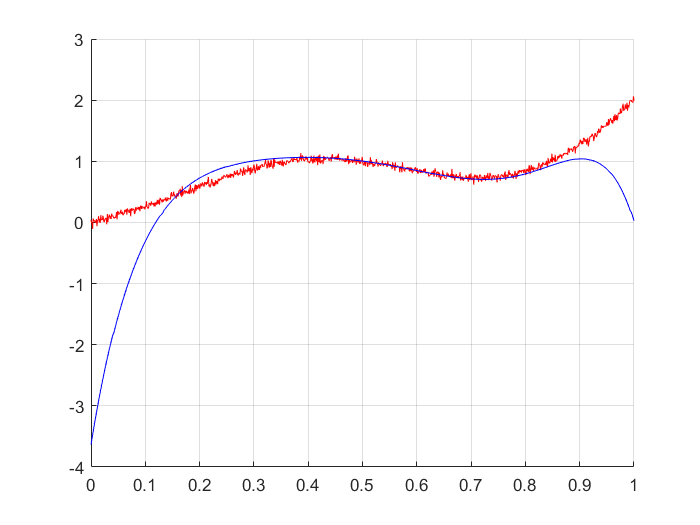

MSE = 137.2129

n = 9

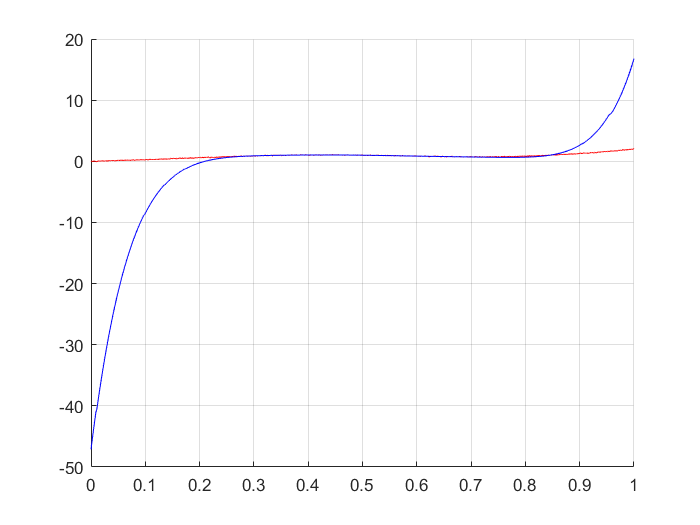

MSE = 1.0929e+04

n = 10

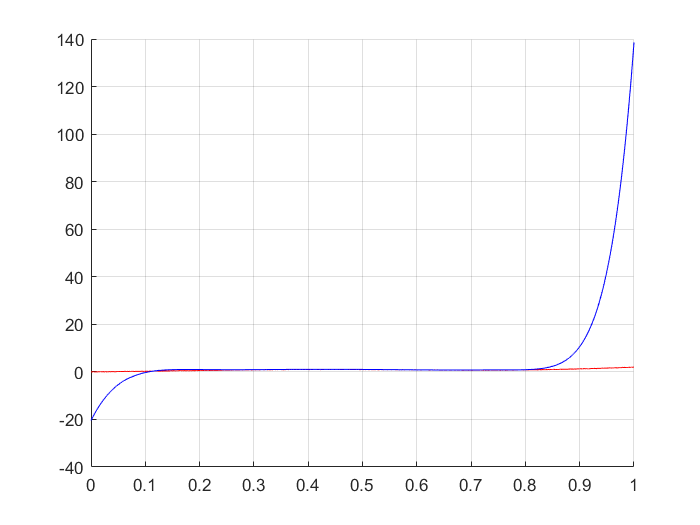

MSE = 1.0803e+05

Training set size 20


n = 1

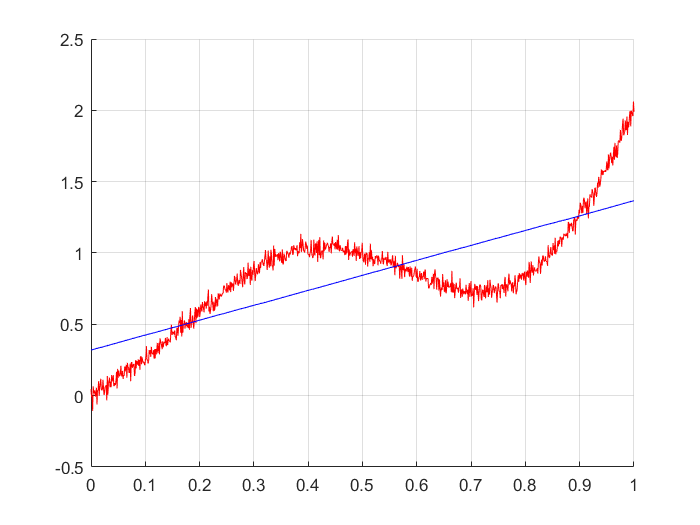

MSE = 0.0658

n = 2

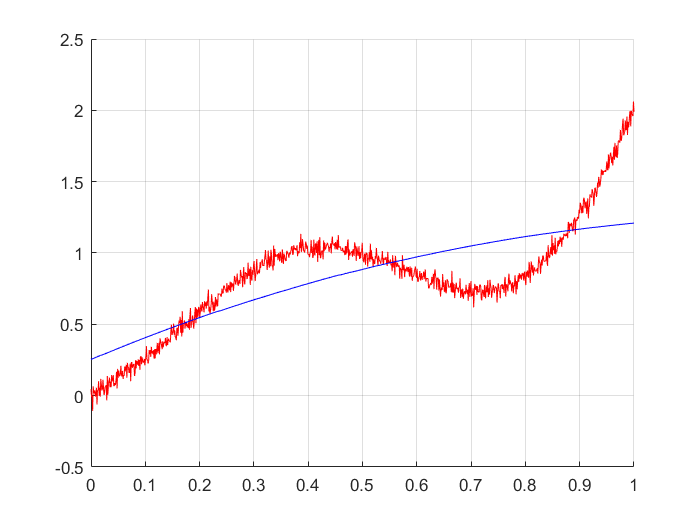

MSE = 0.0800

n = 3

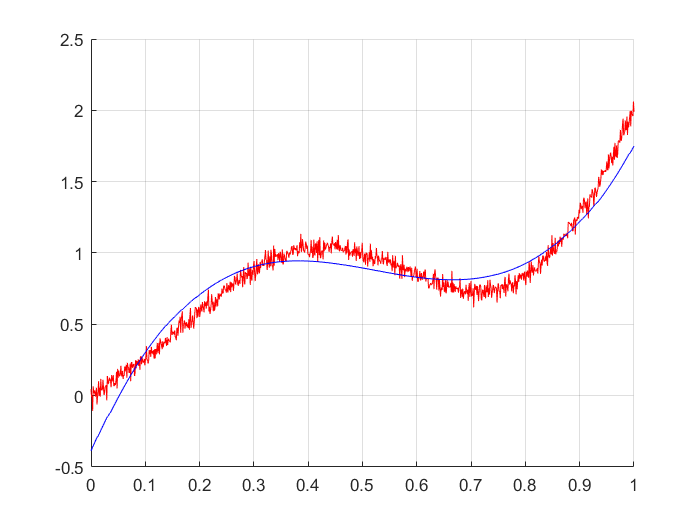

MSE = 0.0428

n = 4

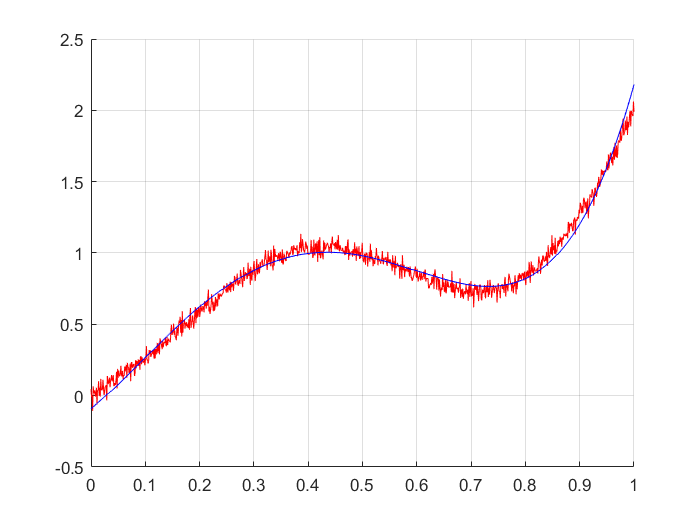

MSE = 0.0059

n = 5

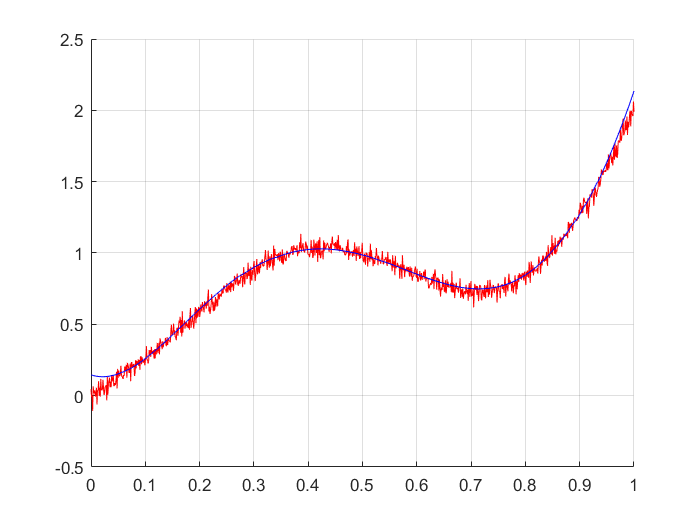

MSE = 0.0077

n = 6

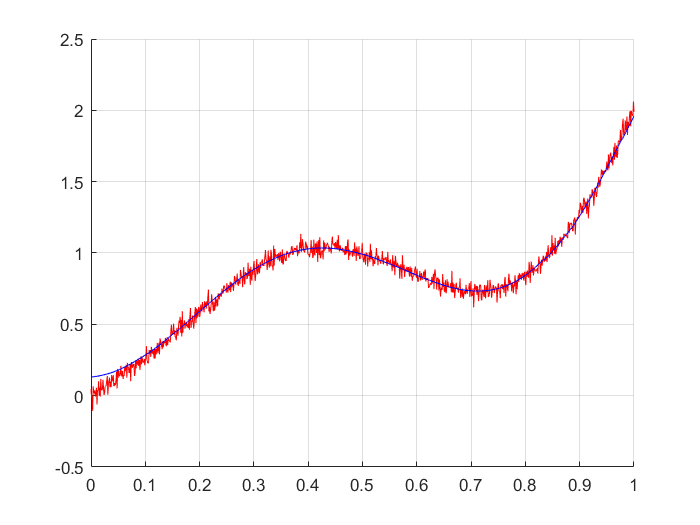

MSE = 0.0449

n = 7

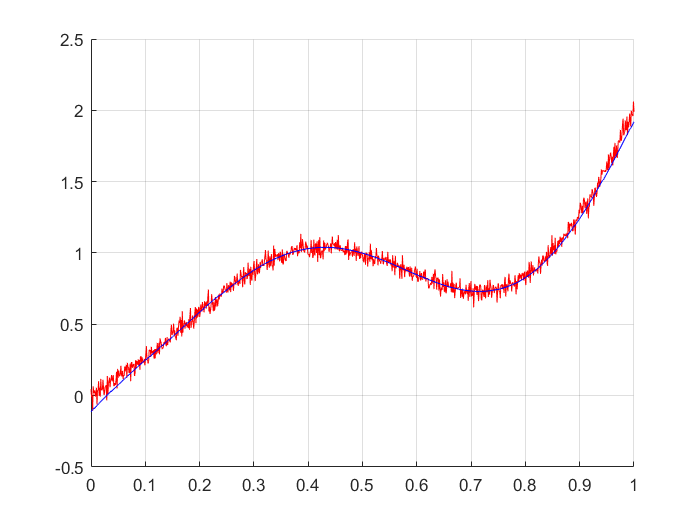

MSE = 0.1634

n = 8

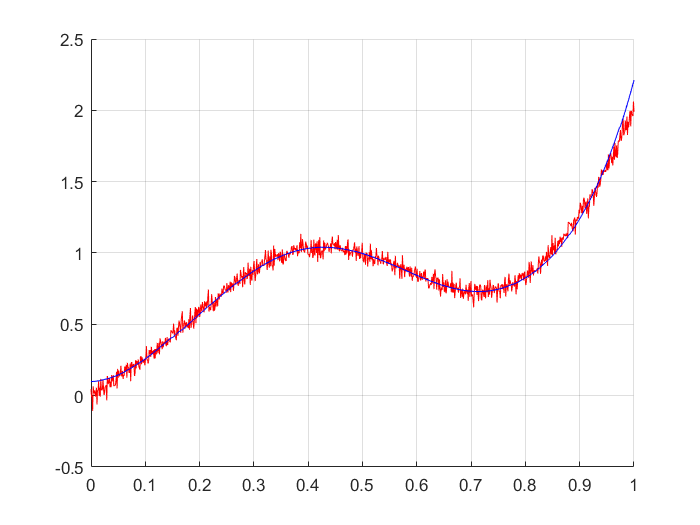

MSE = 0.1621

n = 9

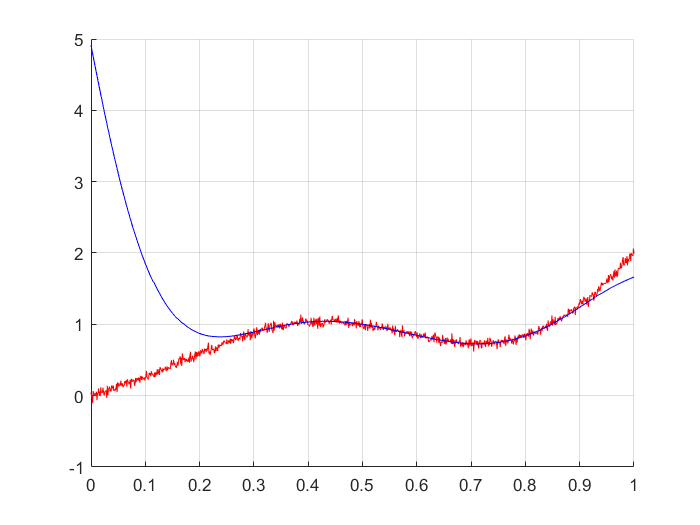

MSE = 606.1834

n = 10

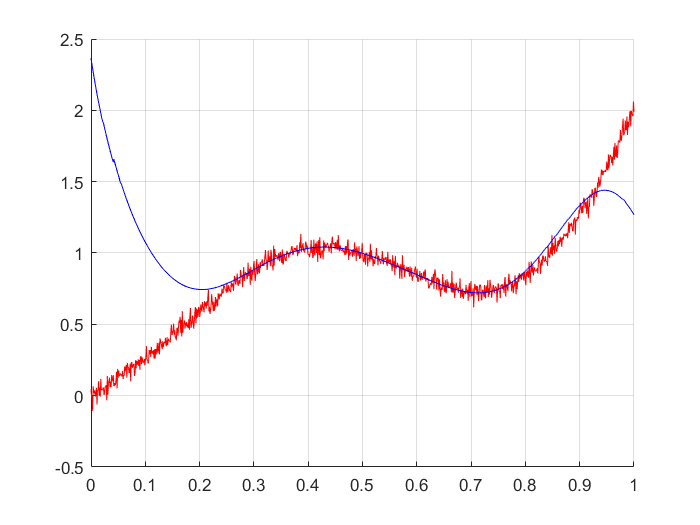

MSE = 36.0688

Training set size 25


n = 1

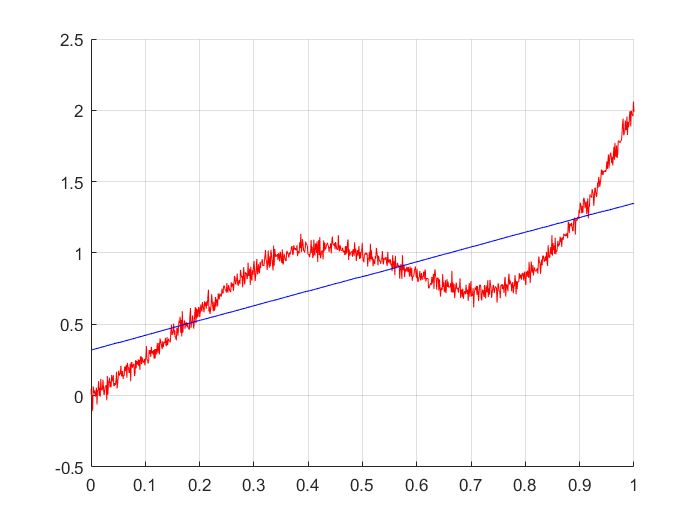

MSE = 0.0634

n = 2

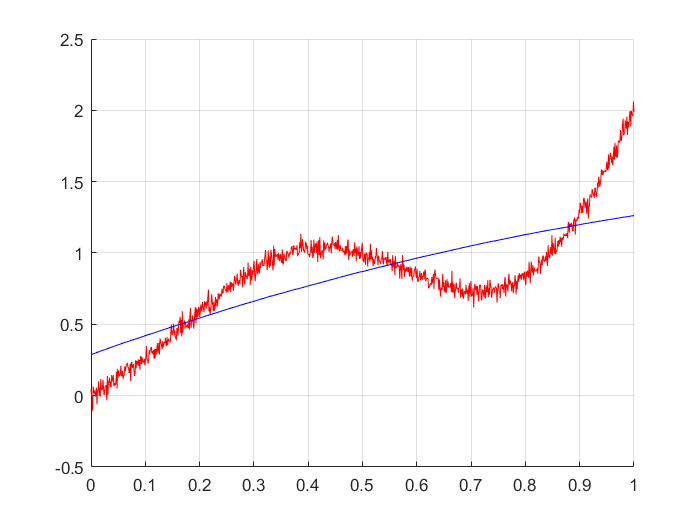

MSE = 0.0679

n = 3

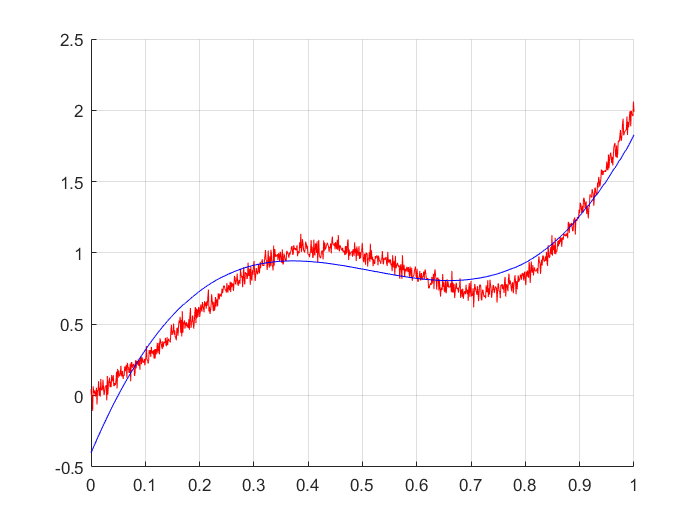

MSE = 0.0200

n = 4

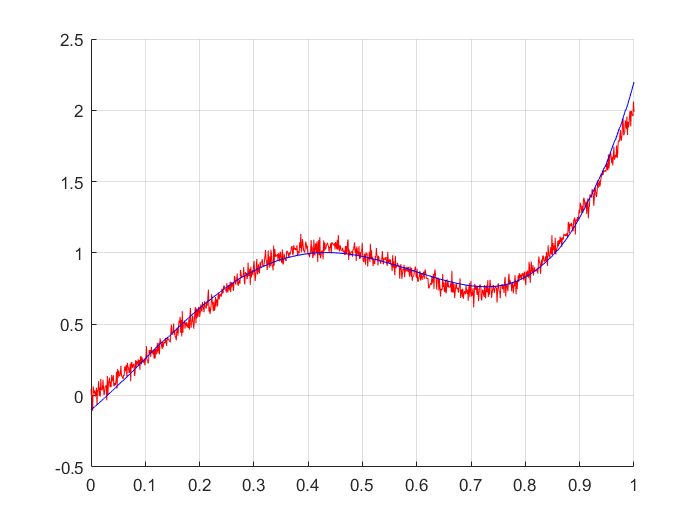

MSE = 0.0069

n = 5

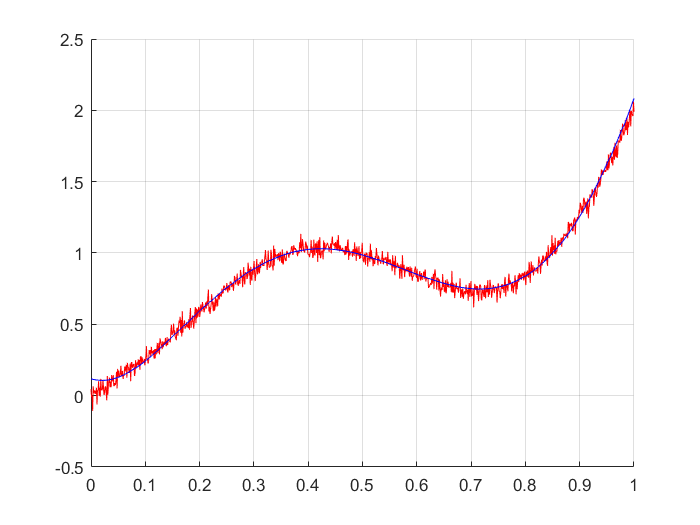

MSE = 0.0038

n = 6

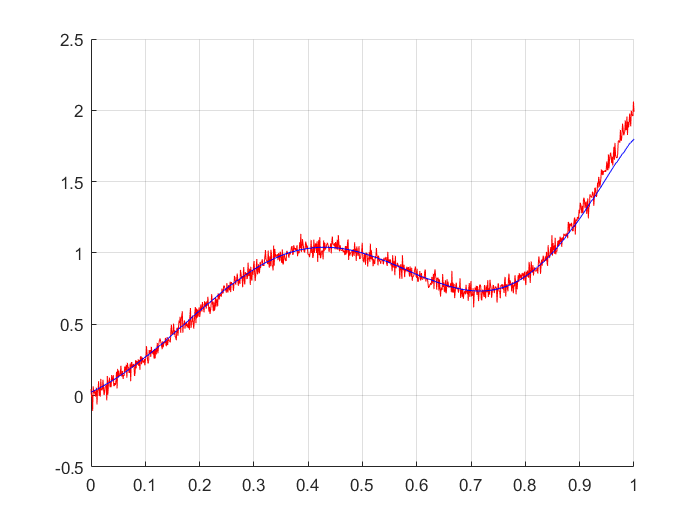

MSE = 0.1507

n = 7

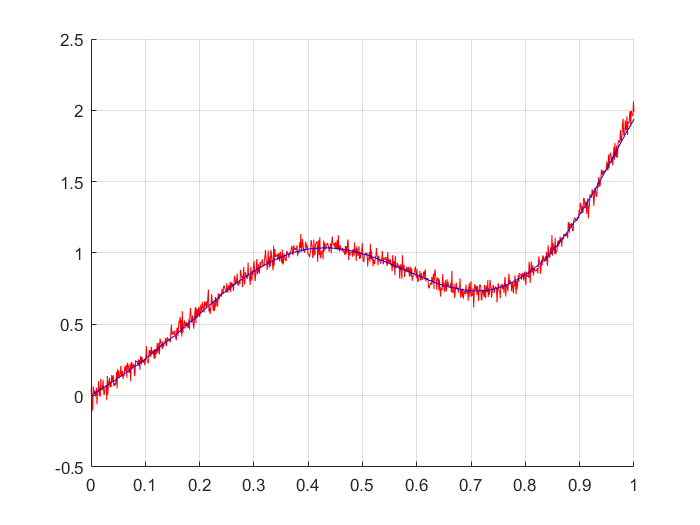

MSE = 0.0088

n = 8

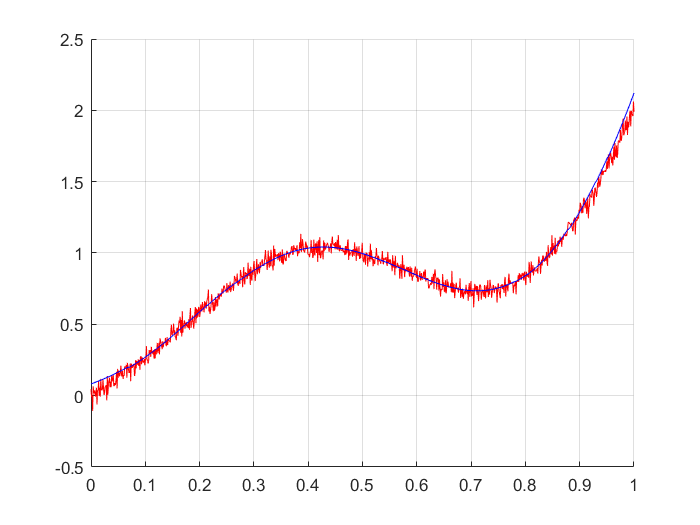

MSE = 0.1786

n = 9

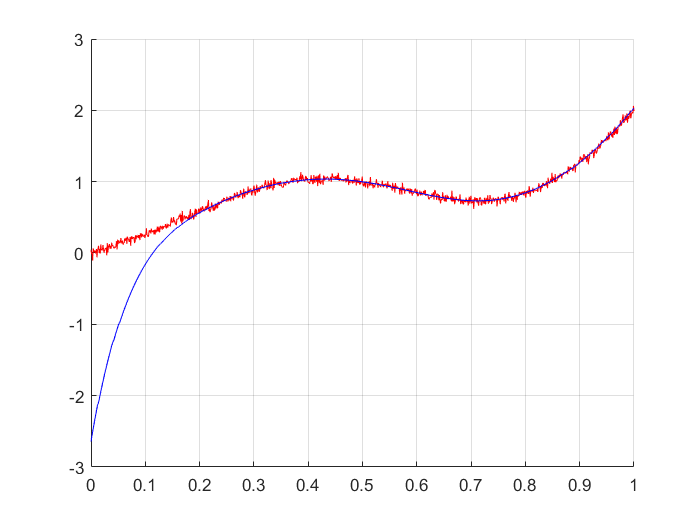

MSE = 17.8661

n = 10

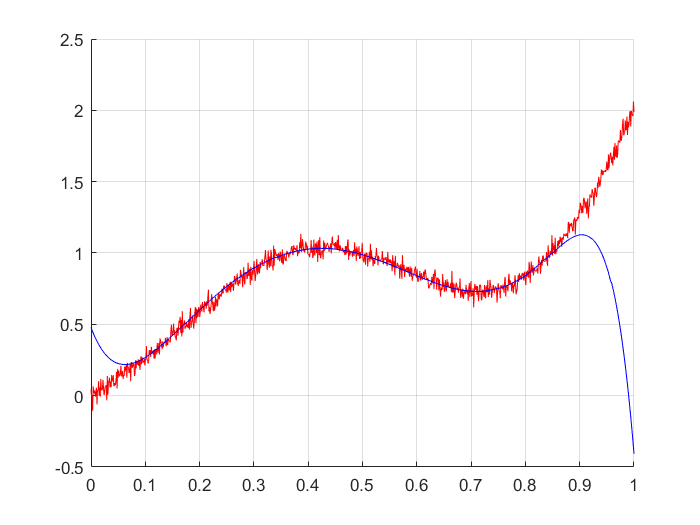

MSE = 13.5005

Training set size 50


n = 1

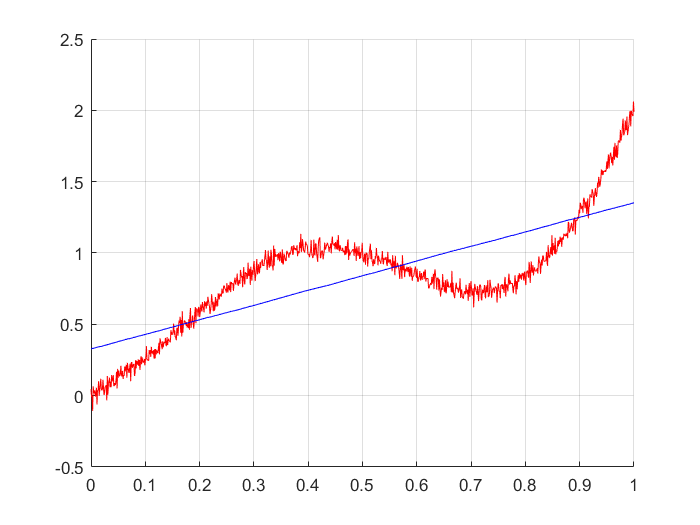

MSE = 0.0594

n = 2

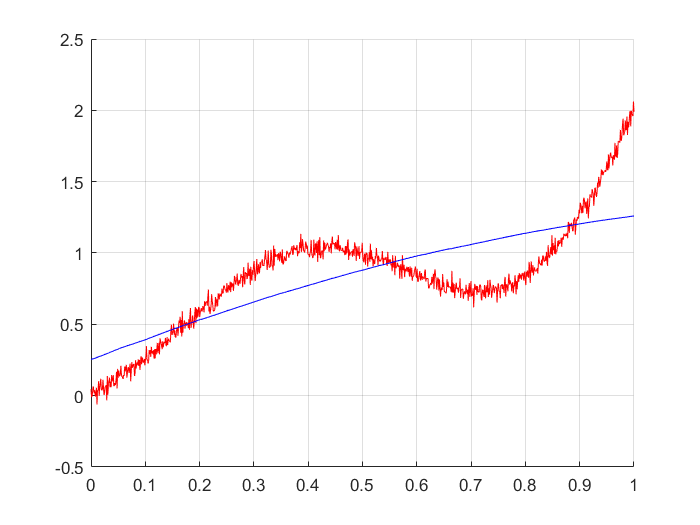

MSE = 0.0606

n = 3

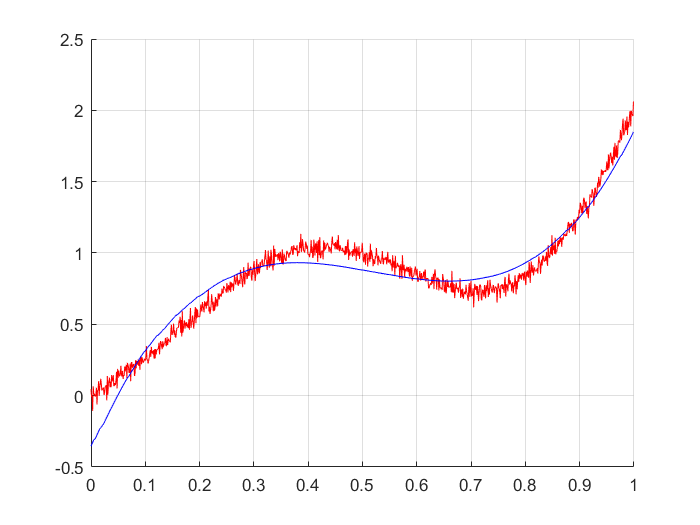

MSE = 0.0134

n = 4

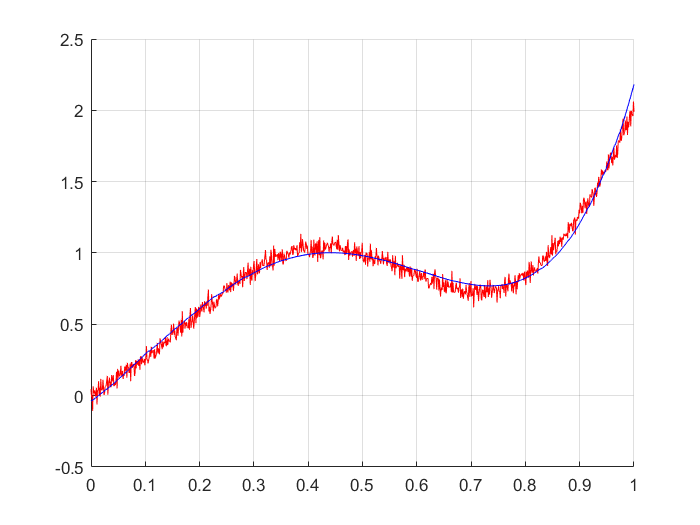

MSE = 0.0034

n = 5

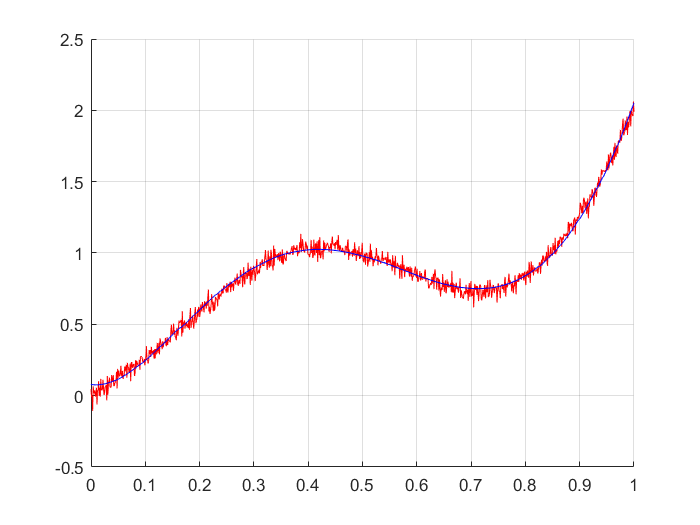

MSE = 0.0021

n = 6

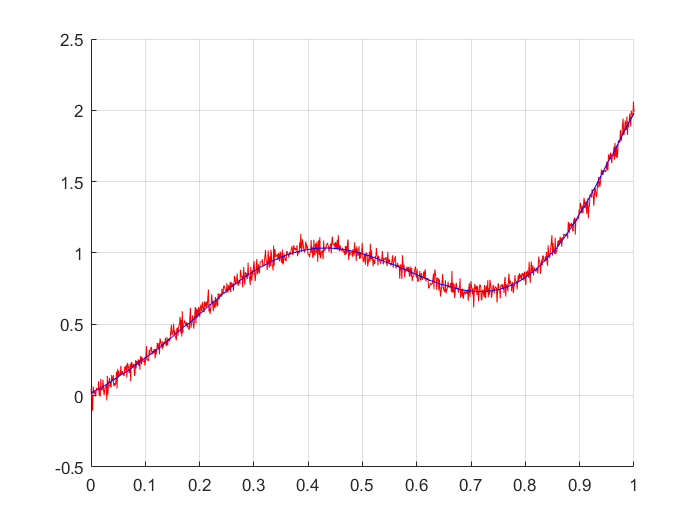

MSE = 0.0019

n = 7

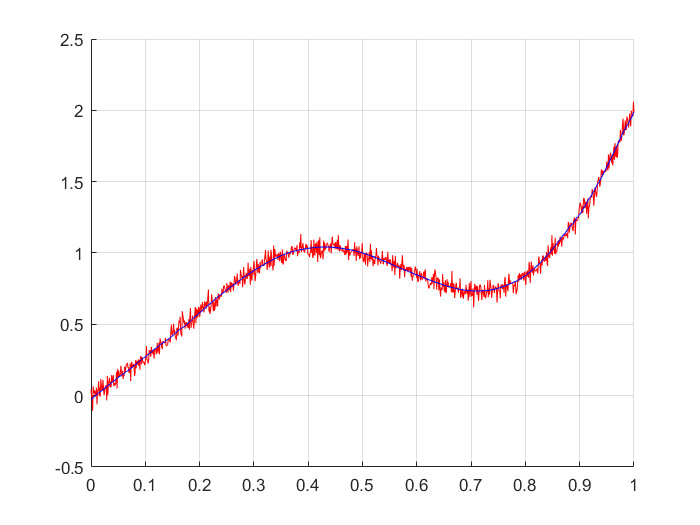

MSE = 0.0021

n = 8

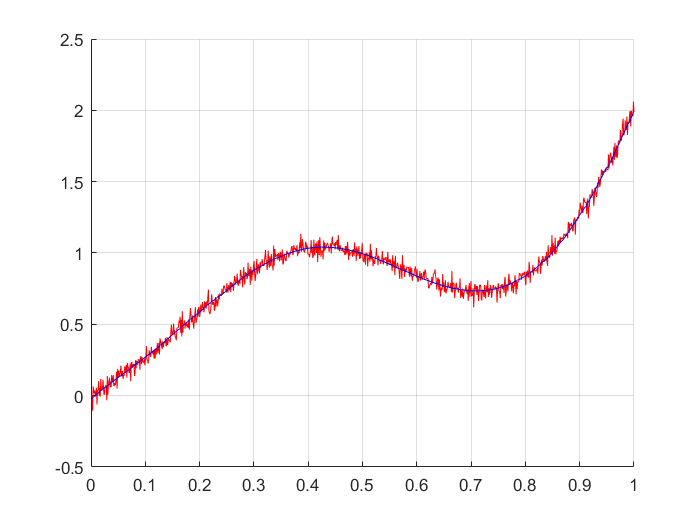

MSE = 0.0022

n = 9

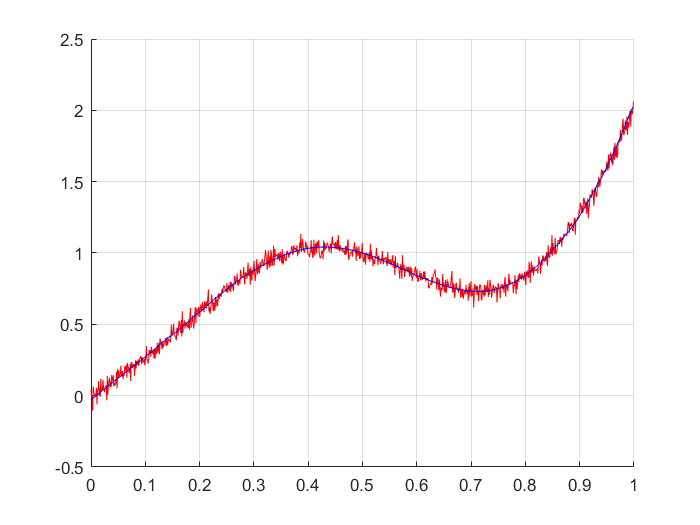

MSE = 0.0037

n = 10

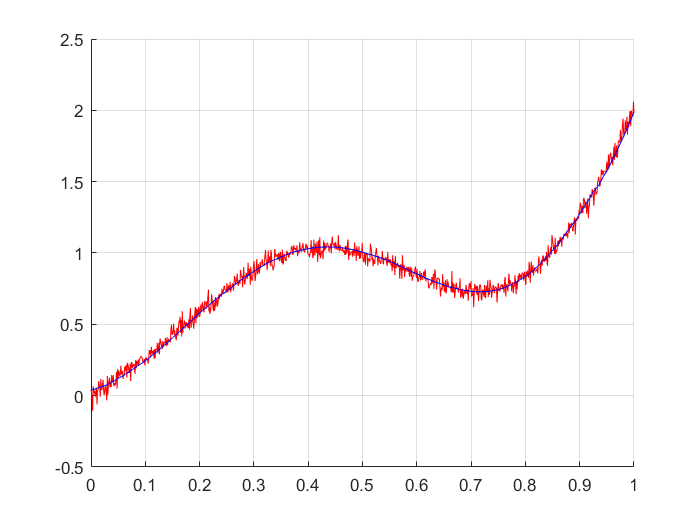

MSE = 0.0074

Training set size 100


n = 1

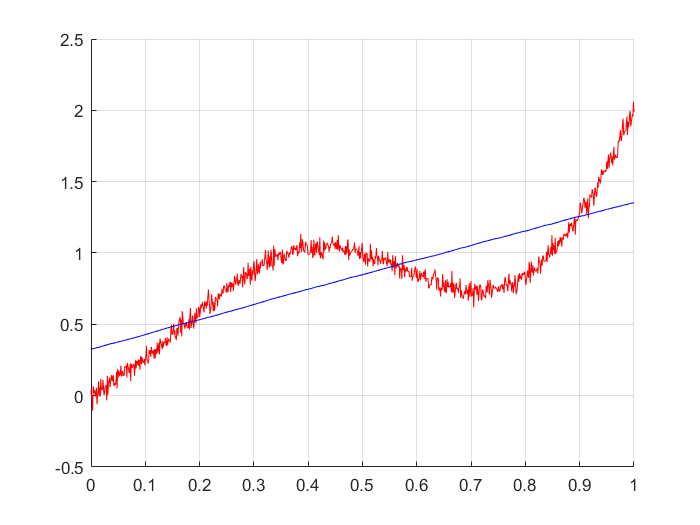

MSE = 0.0550

n = 2

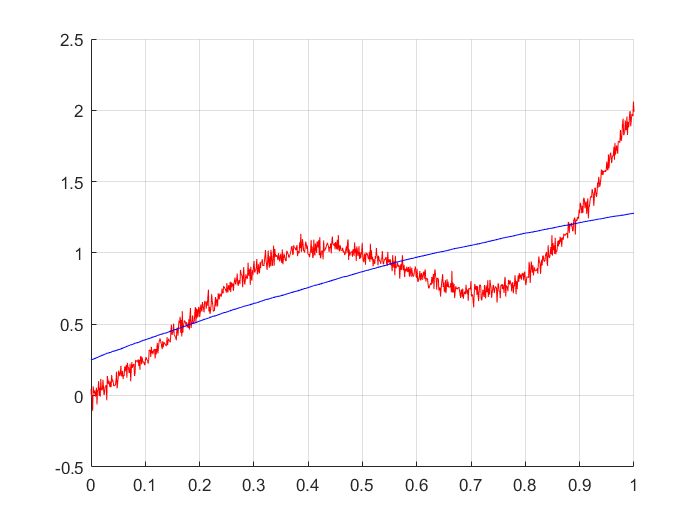

MSE = 0.0559

n = 3

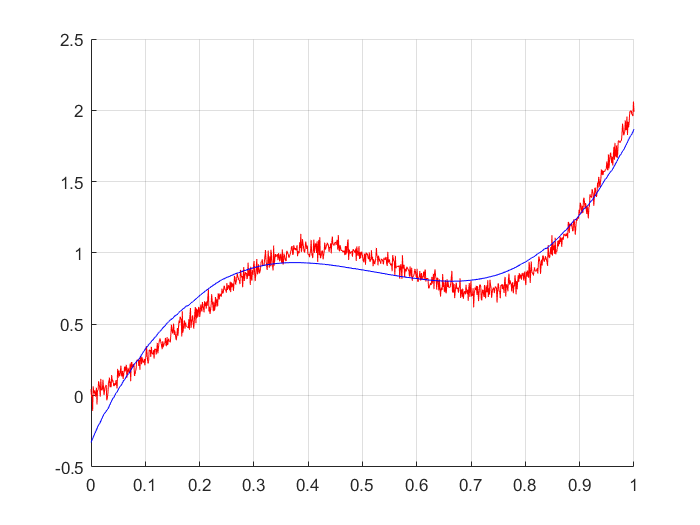

MSE = 0.0111

n = 4

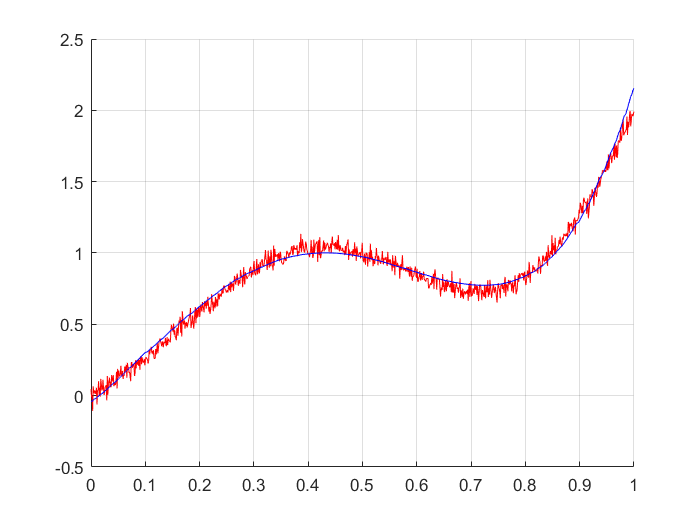

MSE = 0.0027

n = 5

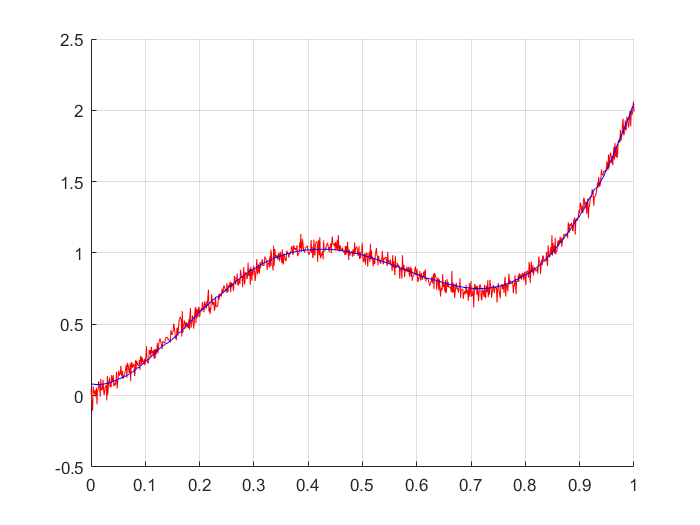

MSE = 0.0018

n = 6

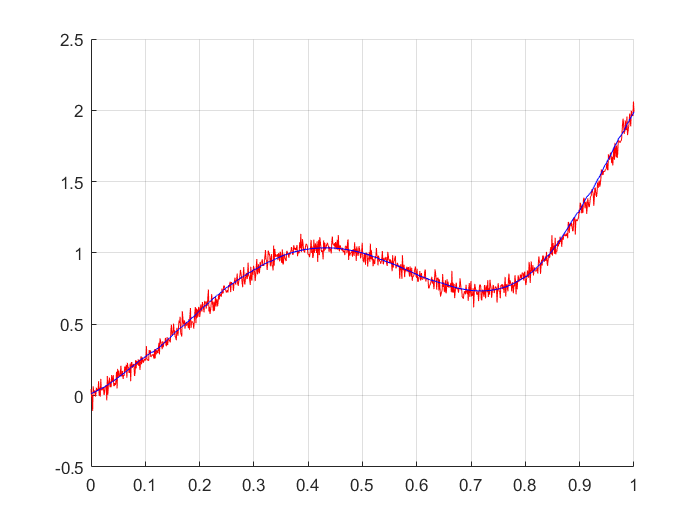

MSE = 0.0015

n = 7

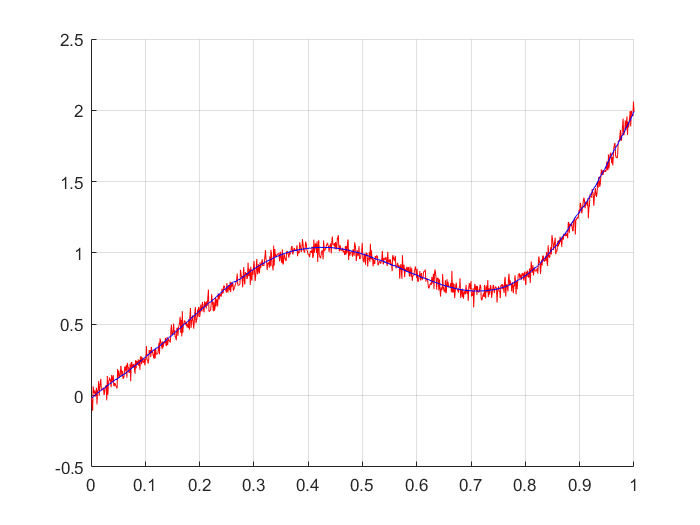

MSE = 0.0015

n = 8

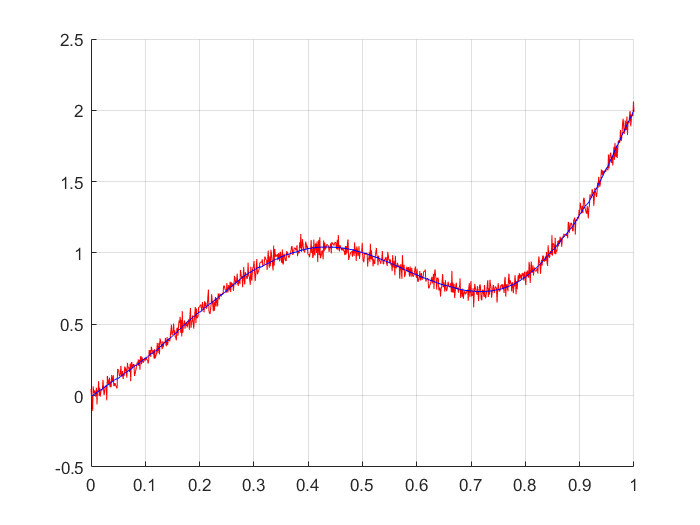

MSE = 0.0015

n = 9

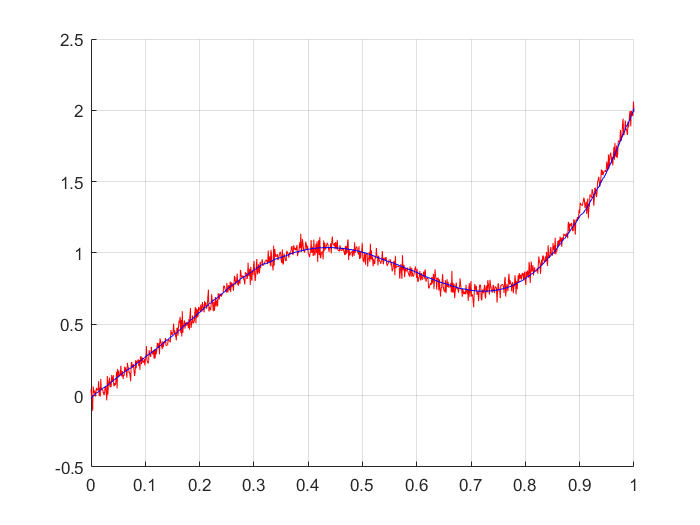

MSE = 0.0016

n = 10

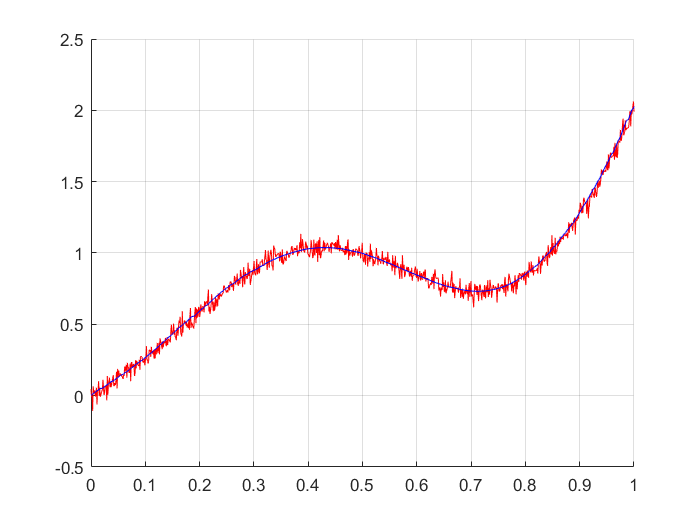

MSE = 0.0017

Training set size 200


n = 1

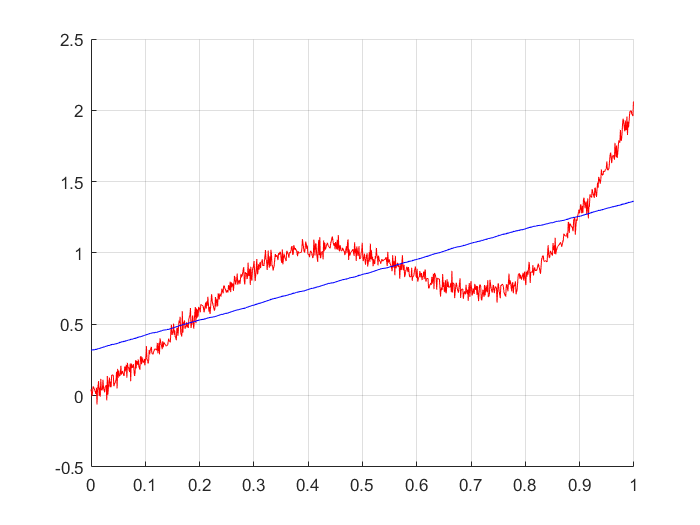

MSE = 0.0483

n = 2

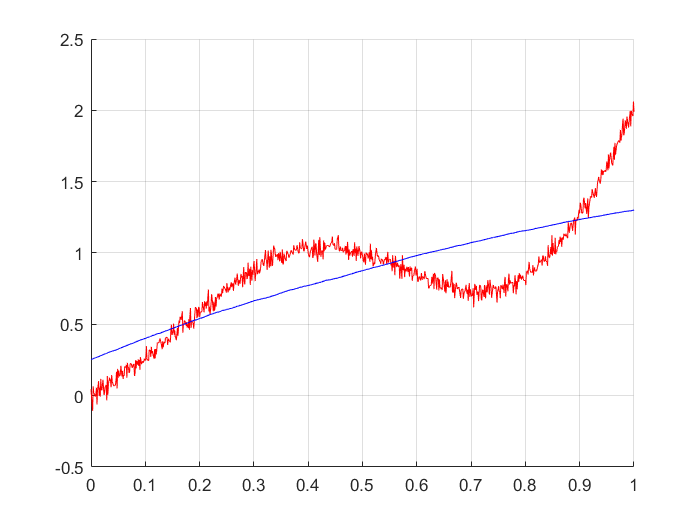

MSE = 0.0482

n = 3

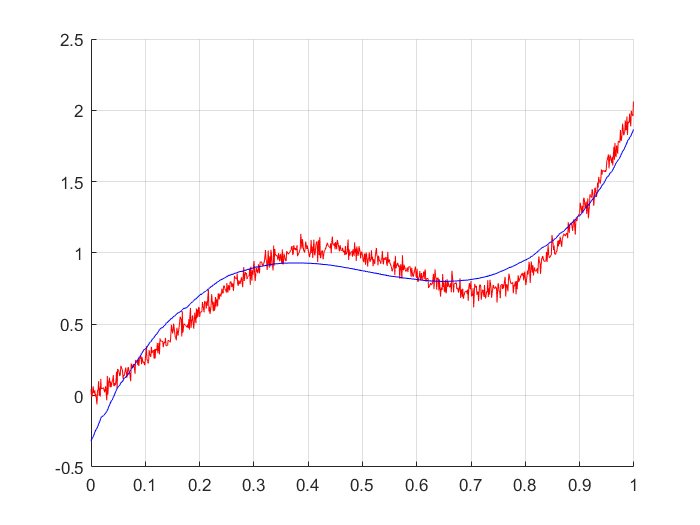

MSE = 0.0096

n = 4

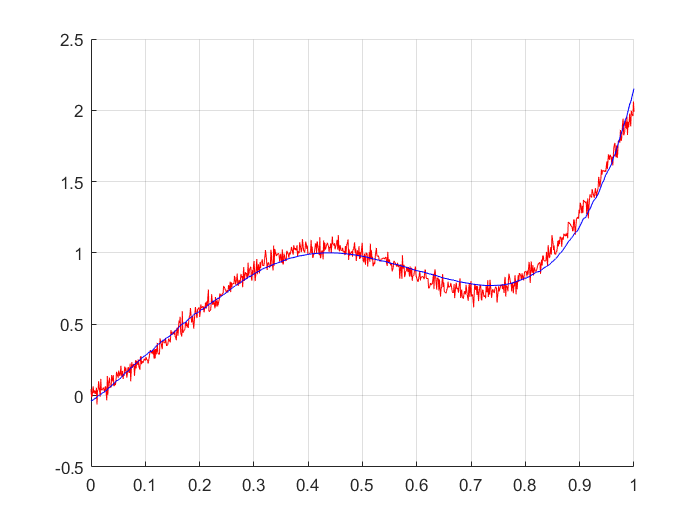

MSE = 0.0023

n = 5

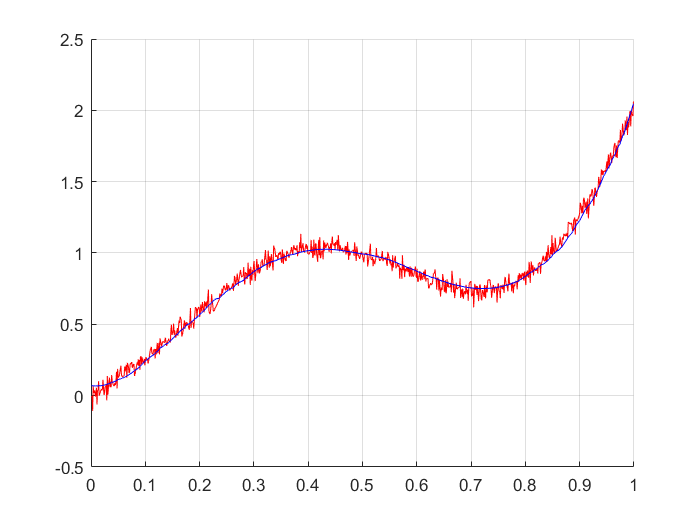

MSE = 0.0015

n = 6

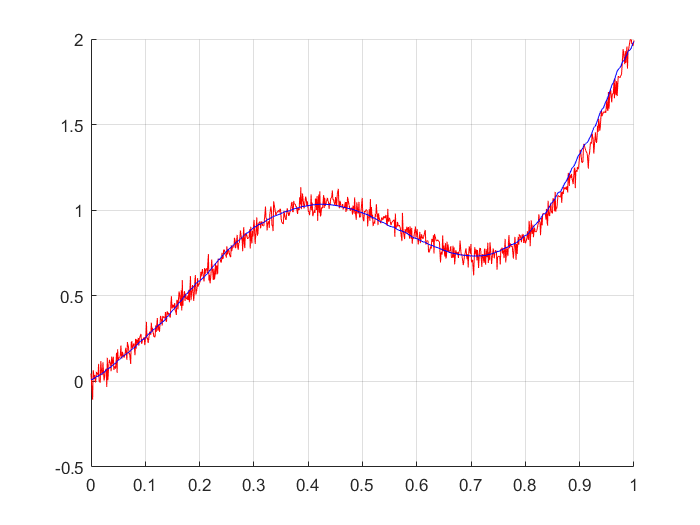

MSE = 0.0013

n = 7

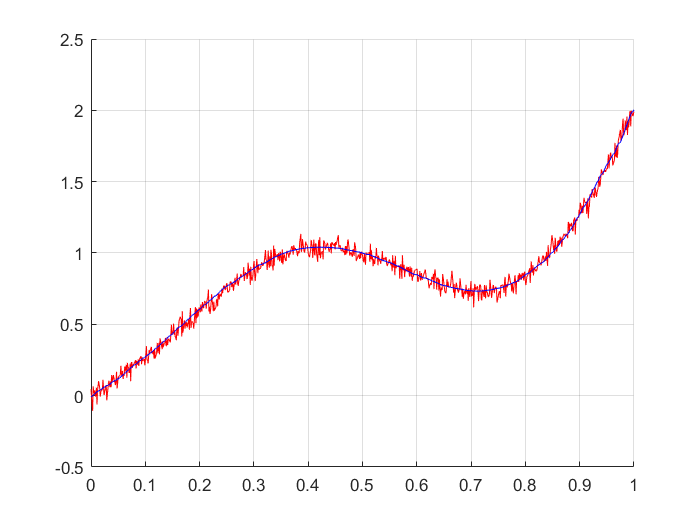

MSE = 0.0013

n = 8

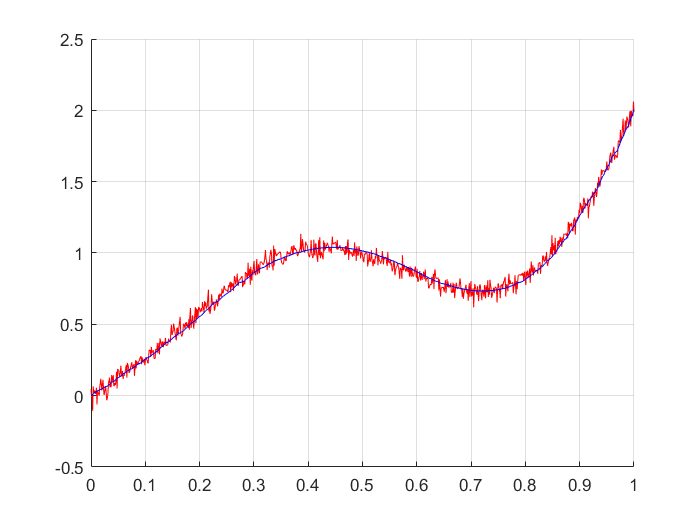

MSE = 0.0013

n = 9

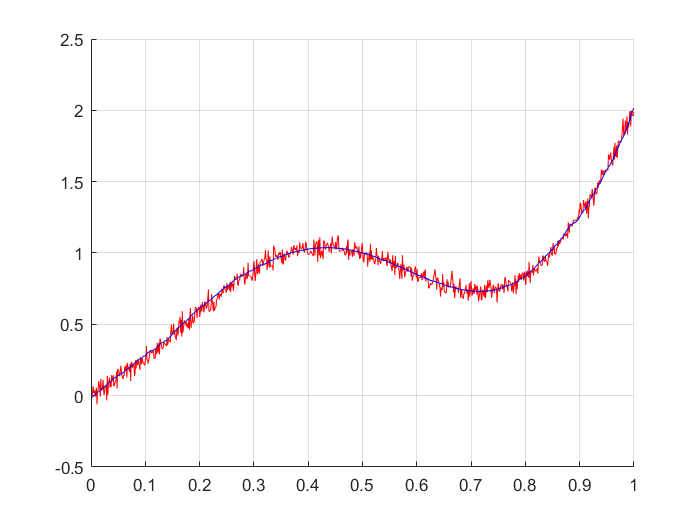

MSE = 0.0013

n = 10

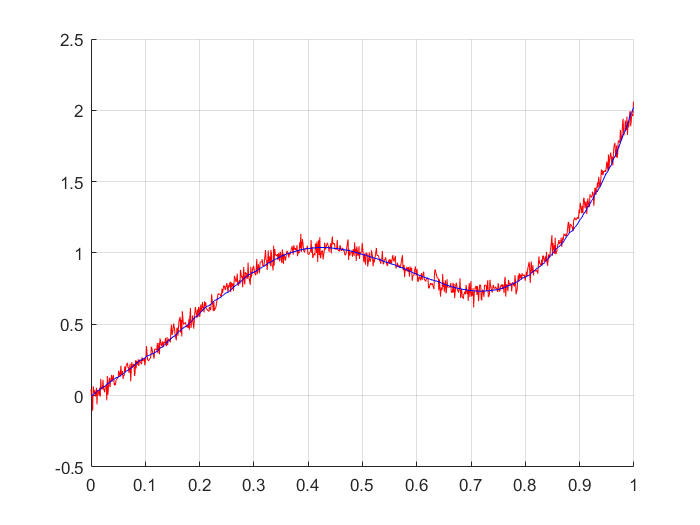

MSE = 0.0013

warning('off','all');
fid = fopen('hw1p5_data.csv');

readData = textscan(fid,'%f %f','Delimiter',',');

X = readData{1,1}(:,1);
Y = readData{1,2}(:,1);
N = numel(X);

data = [X Y];

% cla; hold on; grid on;
% plot(X,Y,'b-')

[Train,idx] = datasample(data,10,'Replace',false);
T = data;
T(idx,:) = [];

% matrix = [1 2 3;3 4 6;3 5 8;9 5 2; 6 9 0]
% [train,idx] = datasample(matrix,2)
% matrix(idx,:) = []

% [p,S] = polyfit(Train(:,1),Train(:,1),1);
% fitY = polyval(p,T(:,1));
% MSE = (sum((fitY - T(:,2)).^2))/N
% cla; hold on; grid on;
% plot(T(:,1),T(:,2),'r-');
% plot(T(:,1),fitY,'b-');

nsamples = [10;15;20;25;50;100;200];
% x = 7;
% for i = 1:10
%     MSE = 0;
%     Ytest = zeros(N-nsamples(x,1));
%     n = i
%     for j = 1:100
%         [train,idx] = datasample(data,nsamples(x,1),'Replace',false);
%         test = data;
%         test(idx,:) = [];
%         
%         [p,S] = polyfit(train(:,1),train(:,2),i);
%         fitY = polyval(p,test(:,1));
%         Ytest(:,j) = Ytest(:,j) + fitY;
%         MSE = MSE + (sum((fitY - test(:,2)).^2))/N;
%     end
%     figure(i);
%     cla; hold on; grid on;
%     plot(test(:,1),test(:,2),'r-');
%     plot(test(:,1),sum(Ytest,2)/100,'b-');
%     MSE = MSE/100
% end

MSEmat = zeros(7,10);
for k = 1:7
    fprintf("Training set size %d\n",nsamples(k,1));
    for i = 1:10
        MSE = 0;
        Ytest = zeros((N-nsamples(k,1)),1);
        n = i
        for j = 1:100
            [train,idx] = datasample(data,nsamples(k,1),'Replace',false);
            test = data;
            test(idx,:) = [];
            
            [p,S] = polyfit(train(:,1),train(:,2),i);
            fitY = polyval(p,test(:,1));
            Ytest = Ytest + fitY;
            MSE = MSE + (sum((fitY - test(:,2)).^2))/N;
        end
        figure((k-1)*10+i);
        cla; hold on; grid on;
        plot(test(:,1),test(:,2),'r-');
        plot(test(:,1),sum(Ytest,2)/100,'b-');
        MSE = MSE/100
        MSEmat(k,i) = MSE;
    end
end


MSEmat = log(MSEmat);

MSEmat(2,10)

ans = 11.5902